# **INICIALIZACAO**

clear all
close all
clc
fn_inicializar_modelo

# **AUTOVALORES**

eig(A)

ans =          0
   -2.4674
   -0.1665
    2.4339


# **CONTROLABILIDADE**

rank(ctrb(A,B))

ans = 4

# **LQR**

Q = diag([10,1,10,10]);
R = 0.001;
K = lqr(A,B,Q,R)

K = 	1.0e+03 *

   -0.1000   -0.1426    1.0125    0.4571


eig(A-B*K)

ans =  -12.0769 + 0.0000i
  -1.8188 + 1.2742i
  -1.8188 - 1.2742i
  -1.6791 + 0.0000i


# **Simulação**

x = $\left[\matrix{x & \dot{x} & \theta & \dot{\theta}} \right]^T$

tspan = 0:.001:15;

x0 = [-1; 0; pi+.4; 0]; % initial condition
wr = [1; 0; pi; 0]; % reference position
% u  =@(tt, xx) fn_controle(tt,xx,K,wr);
u  =@(xx) -K*(xx - wr);

[t,x] = ode45(@(t,x)fn_eq_diferencial(x,m,M,L,g,d,u(x)),tspan,x0);

# **ANIMACAO**

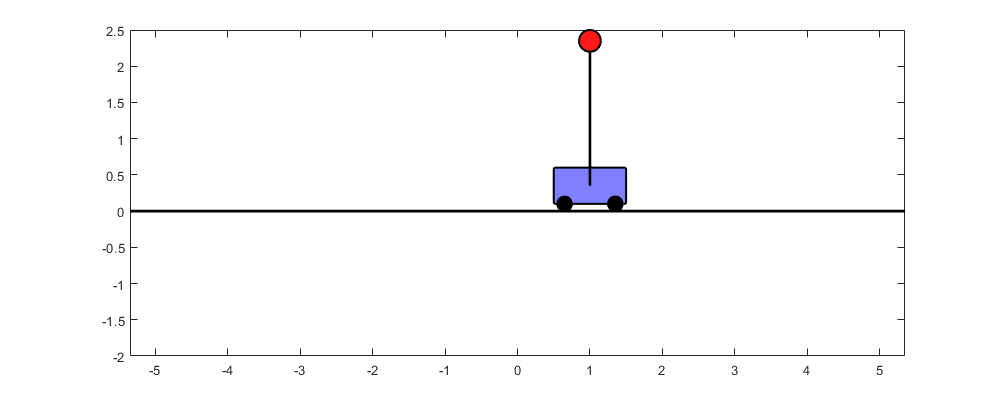

passo = 200;
fn_animacao_carro(t, x, m, M, L, passo);

# **GRAFICO ESTADOS**

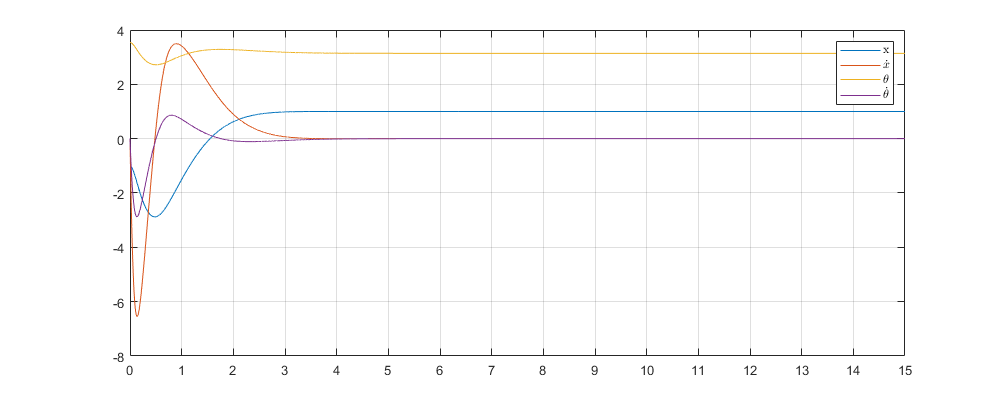

h = plot(t,x); 

leg = legend('x', '$\dot{x}$', '$\theta$', '$\dot{\theta}$');
set(leg,'Interpreter','latex');
grid on;
h(1).Parent.XTick = [0:1:15];